# Control and Instrumentation Lab Assignment 2

**SWARNENDU PAUL 19EE3FP18**

**Question 7.**

Creating grid:

x=-1:0.05:1;
[y1,y2]= meshgrid(x);

Now we will find the phase portrait of y1 and y2 for the given set of points.

vy1=y2;
vy2=-4.9*sin(y1);

Plotting using quiver command

figure(1)
quiver(y1,y2, vy1, vy2)

Next we will solve the ODE using initial condition y1=0, y2=0.5

The plot of y1 and y2 we get from solving the ODE is also shown in the figure. the 'orange circle' denotes the starting point at t=0s. and 'purple square' denotes the end point at t=20s while the red line shows the variation of angular velocity vs angular displacement of the undamped pendulum.

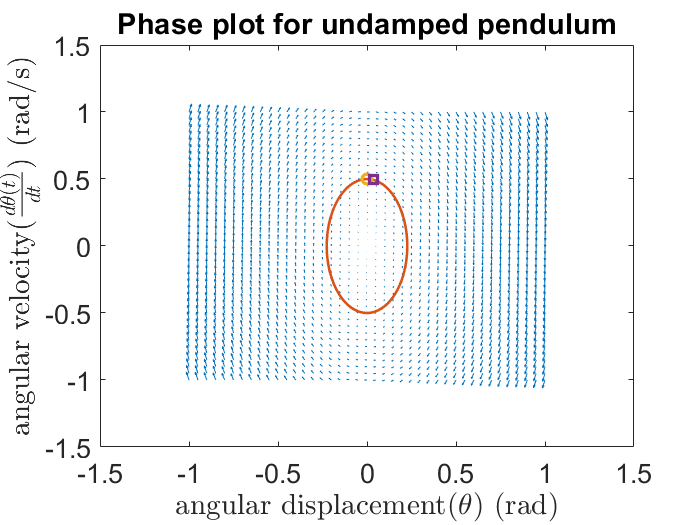

t=0:0.01:20;
[t,y]=ode45(@pen1,t,[0 0.5]);
hold on
plot(y(:,1),y(:,2),'LineWidth',1.5);
plot(y(1,1),y(1,2),"LineWidth",2,"Marker","o");
plot(y(2001,1),y(2001,2),"LineWidth",2,"Marker","square");
xlabel("angular displacement($\theta$) (rad)","Interpreter","latex")
ylabel("angular velocity($\frac{d\theta(t)}{dt}$) (rad/s)","Interpreter","latex");
set(gca,'Fontsize',16);
title("Phase plot for undamped pendulum");
hold off

Now we will do the same calculation and plotting using **damping coefficient b=0.3** to observe the behaviour of damped pendulum.

Meshgrid is already created so we can move to finding the phase portrait from the ODE saved in pen2.m for damped pendulum.

vy1=y2;
vy2=-0.3*y2-12.25*sin(y1);

Plotting using quiver command

figure(2)
quiver(y1,y2,vy1,vy2);

Next we will solve the ODE using initial condition y1=0, y2=0.5

The plot of y1 and y2 we get from solving the ODE is also shown in the figure. the 'orange circle' denotes the starting point at t=0s. and 'purple square' denotes the end point at t=20s while the red line shows the variation of angular velocity vs angular displacement of the damped pendulum.

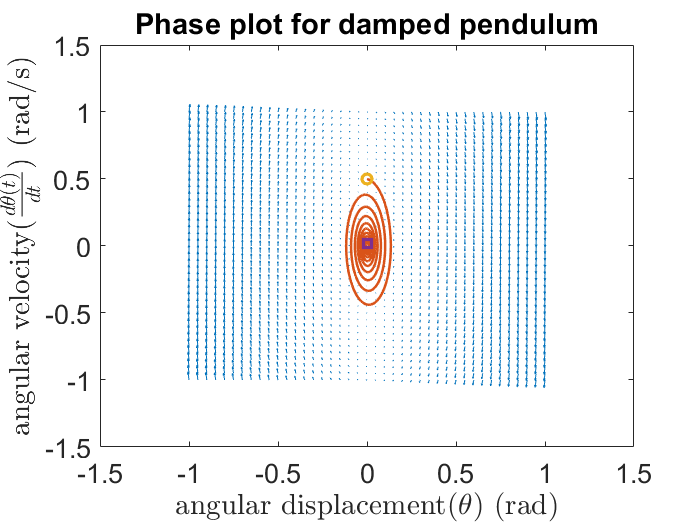

[t,y]=ode45(@pen2,t,[0 0.5]);
hold on
plot(y(:,1),y(:,2),'LineWidth',1.5);
plot(y(1,1),y(1,2),"LineWidth",2,"Marker","o");
plot(y(2001,1),y(2001,2),"LineWidth",2,"Marker","square");
xlabel("angular displacement($\theta$) (rad)","Interpreter","latex")
ylabel("angular velocity($\frac{d\theta(t)}{dt}$) (rad/s)","Interpreter","latex");
set(gca,'Fontsize',16);
title("Phase plot for damped pendulum");
hold off

As observed in Question no. 5, the angular velocity as well as angular displacement gradually decreases with time due to damping. While without damping the pendulum follows periodic motion.